# Saltwater Intrusion

## Introduction 

Saltwater intrusion is when seawater infiltrates freshwater sources. It is important to track saltwater intrusion of aquifers because groundwater is a critical source of drinking water for many people in the United States. As sea levels rise, freshwater coastal aquifers will be more threatened by saltwater intrusion, putting populations and communities that depend on coastal aquifers at risk of losing their freshwater drinking source. Additionally, coastal agriculture is impacted by saltwater intrusion, where salt deposits interact with soil chemistry and can be harmful to plants (USDA, 2019 & USGS, n.d.) The rate at which aquifers are being affected varies, so having a model to accurately predict salt water intrusion can help determine which areas need more immediate action for prevention and mitigation strategies (Barlow & Reichard, 2010). The main theme of this research paper is developing a model for salt water intrusion based on previous work by Mark Bakker. Understanding the dynamics of saltwater intrusion is a pressing issue with dedicated annual/biannual meetings to share new developments at the Salt Water Intrusion Meeting.

While our model was not based on a specific geographical location where saltwater intrusion occurs, other studies were conducted as case studies in set geographical locations and used more dimensions to create a more accurate model (Bouzouf et al., n.d.). Other models have also used similar assumptions to Bakker, but compared more accurate methods such as the partial Newton and partial Picard methods (Putti & Paniconi, 1995).  Additionally, more robust models have been developed, such as the Sea Water Intrusion (SWI2) package for MODFLOW, a model used by the United States Geological Survey (Bakker et al., 2013).

## **Equations**

**Fundamental physical processes**

Saltwater intrusion is when seawater comes into contact with freshwater sources. This occurs most often through sea level rise when higher tides begin impacting areas of low elevation and when seawater infiltrates freshwater aquifers (USDA, 2019 & USGS, n.d.) Excess pumping of groundwater in coastal areas can also promote saltwater intrusion into aquifers (USGS, n.d.). This model aims to simulate the intrusion of saltwater into a freshwater aquifer under set initial conditions.

**Relevant equations**

Equation 1 is the differentiated discharge vector, which was obtained from the vertically integrated flux (discharge) vector under the Boussinesq approximation.

Equation 2 is the differentiation of the salt discharge vector, obtained from the vertically integrated flux vector in the saltwater zone (salt discharge).

Assuming a steady state given Equation 3:

the Ghyben-Herzberg condition (Equation 4) is used to calculate h.

Glover’s formula was applied to determine boundary conditions.  

clear 
clc

**Describe all terms and parameters:**

All terms and parameters are listed below. No value was given for infiltration of freshwater (N), so its value was assumed. 

k = 2; % hydraulic conductivity [m/day]
porosity = 0.2; % effective porosity (defined as n in the paper)
S = 1; % storage coefficient
H = 45; % thickness of aquifer [m]
zb = -45; % bottom of aquifer [m]
zt = 0; % top of aquifer [m]
L = 1000; % length of cross section [m]
W = 1; % width of cross section normal to plane of flow [m]
vs = 0.025; % dimensionless density
T = k*(zt-zb); % transmissivity of freshwater
tau = k*vs*(zt-zb); % transmissivity of saltwater
N = 1; % infiltration of freshwater
Q_0 = 0.1; % uniform flow towards the coast (boundary condition) [m2/day]

stepping variables:

dx  = 10; % space step [m]
xf = L; 
xvec = [0:dx:xf];
dt = 0.5; % time step [years]
tf = 500; % final time [years]


**Assumptions**

Based on assumptions by Bakker (Bakker, 2000):

- The resistance to flow in the vertical direction is neglected (Dupuit approximation)

- Mass balance is replaced by volume balance (Boussinesq approximation)

- Density difference between freshwater and saltwater is 2.5%

- Groundwater flow is horizontal

- Freshwater and saltwater are immiscible

## **Numerical Methods**

We use the forward Euler method to solve this coupled system of PDEs. While there are more accurate models to solve these PDEs, forward Euler is most approachable and similar to the block-centered finite difference method used by Bakker.

The boundary conditions for each simulation were defined as follows:

At x = 0, zeta = -2 and h = 0.05. At x = 1000, h = -zeta*vs as defined by equation (4) and zeta = zb, or the bottom of the aquifer.

**setting up matrices**

m = round(xf/dx + 1); % # of space steps
n = round(tf/dt + 1); % # of time steps

for equation 1:

% template matrix for h
A =  T*dt/(dx^2*S); % diffusivity term
M = speye(m,m);
for i = 1:m
    for j = 1:m
        if i == j
            M(i,j) = 1-2*A;
        elseif i-1== j
            M(i,j) = A;
        elseif i+1 == j
            M(i,j) = A;
        end
    end
    
end 

boundary conditions for h

% Dirichlet boundary conditions

M(1,1) = 1;
M(1,2) = 0;
M(m,:) = 0;
M(m,m) = 1;

coupled portion:

S1 = speye(m,m);
B = tau*dt/(S*dx^2);
for i = 1:m
   for j = 1:m
       if i == j
           S1(i,j) = -2*B;
       elseif i-1==j
           S1(i,j) = B;
       elseif i+1 ==j
           S1(i,j) = B;
        end
    end
end 

boundary condtions for coupled zeta matrix:

S1(1,1) = 1;
S1(1,2) = 0;
S1(m,:) = 0;
S1(m,m) = 1;

for equation 2:

O = speye(m,m);
C = (tau*dt/(dx^2*porosity));
for i = 1:m
    for j = 1:m
        if i == j
            O(i,j) = 1-2*C;
        elseif i-1==j
            O(i,j) = C;
        elseif i+1 ==j
            O(i,j) = C;
        end
    end  
end 

boundary conditions for zeta matrix:

% Dirichlet boundary conditions
O(1,1) = 1;
O(1,2) = 0;
O(m,:) = 0;
O(m,m) = 1;

coupled portion:

S2 = speye(m,m);
D = tau*dt/(vs*dx^2*porosity);
for i = 1:m
   for j = 1:m
       if i == j
           S2(i,j) = -2*D;
       elseif i-1==j
           S2(i,j) = D;
       elseif i+1 ==j
           S2(i,j) = D;
       end
    end   
end 

boundary conditions for coupled h matrix:

S2(1,1) = 1;
S2(1,2) = 0;
S2(m,:) = 0;
S2(m,m) = 1;

**solving the matrix problem**

create empty matrices to store solutions

h_all = zeros(m,n);
zeta_all = zeros(m,n);

Initial conditions for zeta were determined by using [Web Plot Digitzer](https://apps.automeris.io/wpd/) to extract the initial interface elevation from Figure 1a in Bakker, and plot it using a 3rd order polynomial line of best fit (shown in Figure X below)

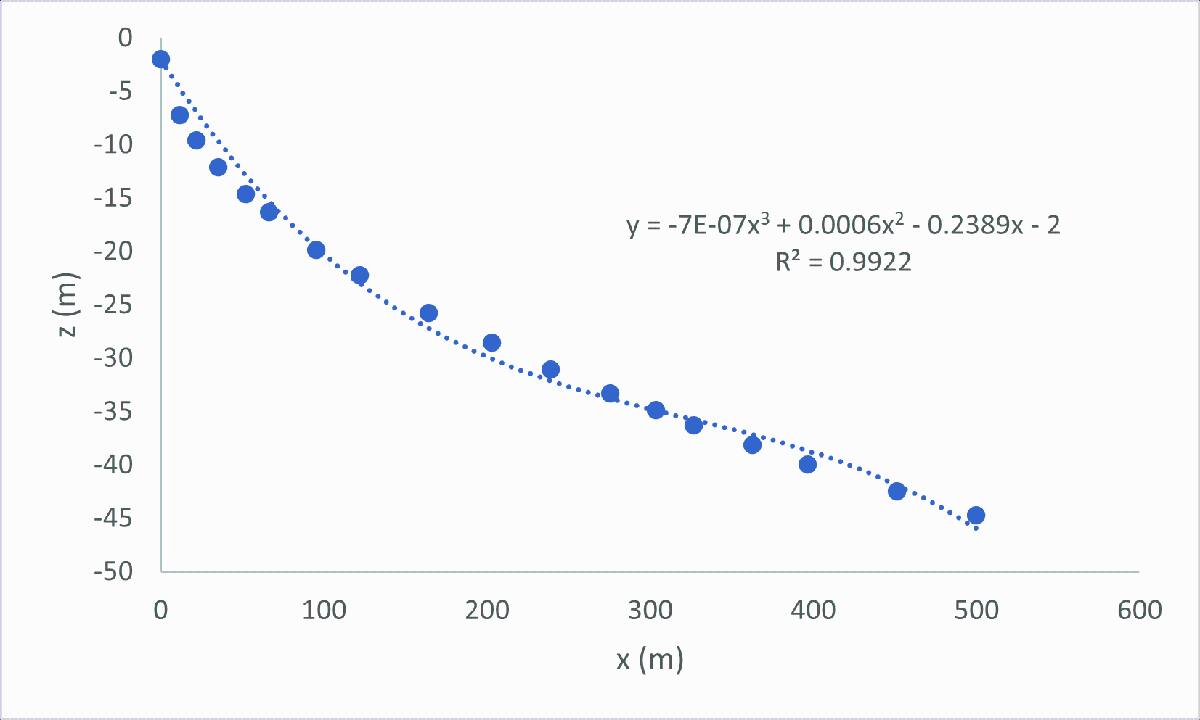

Figure X. Line of best fit for initial conditions of interface elevation (zeta)

zeta = -7E-07*xvec.^3 + 0.0006*xvec.^2 - 0.2389*xvec - 2; 

zeta(40:end) = zb; % where the interface meets the bottom of the aquifer, it cannot go any deeper
zeta = zeta';
zeta_all(:,1) = zeta;



initial conditions for h

h = -zeta*vs; % equation 4: Ghyben-Herzberg
h_all(:,1) = h;


solve the coupled PDEs

for t = 2:n
    hnew = M*h + S1*zeta + (N*dt/S);
    h_all(:,t) = hnew;

    zetanew = O*zeta + S2*h;
    zeta_all(:, t) = zetanew;

    h=hnew;

    zeta = zetanew;
  
end
figure (1)
plot(xvec, zeta_all(:, 1), xvec, zeta_all(:,end)', 'linewidth', 5)
alabel = ['conditions at t= ', num2str(tf)];
legend('initial conditions', alabel)

## **Results**

We attempted to simulate Figure 1a created by Bakker under the following conditions:

dx =10, dt = 0.5, S = 0, N = 0. Results are plotted below in Figure X. 

Figure X is the original figure from Bakker. Comparing Figures Xand X, the general trendline of the graphs is similar.

**Describe the results:**